clc; clear all; close all;

z0 = rand(10,1); % [K(1:6); K1(1:2); K2(1:2)]
syms x [3 1]
syms u [2 1] 
syms t

A = jacobian(plant(t,x,u), x); 
B = jacobian(plant(t,x,u), u); 

xd = zeros(3,1); ud = zeros(2,1); 
A = double(subs(A, [x; u], [xd; ud])) 

A =      0     1     0
     0     0     1
     1     1     0


B = double(subs(B, [x; u], [xd; ud]))

B =      0     0
     1    -1
     1     0



i = 1; % Tipo de costo
[zopt, Jopt] = fmincon(@(z)costo(z,i), z0, [], [], [], [], [], [], @(z)restr(z,A,B));


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



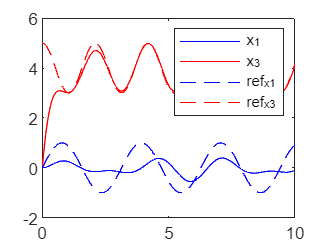

x0 = [0; 0; 0]; % Estado inicial
[T, X] = ode45(@(t,x) plant(t,x,control(t,x,zopt)), [0 10], x0);

y_ref = @(t) [sin(2*t); 4 + cos(3*t)];
Yref = arrayfun(y_ref, T, 'UniformOutput', false);
Yref = cell2mat(Yref')';

figure; 
plot(T, X(:,1), 'b'); hold on;
plot(T, X(:,3), 'r');
plot(T, Yref(:,1), '--b');
plot(T, Yref(:,2), '--r');
legend('x_1','x_3','ref_x1','ref_x3');

function dx = plant(~, x, u)
    dx = [x(2);
          x(3) + u(1) - u(2);
          x(1) + x(2) + u(1)];
end


function u = control(t, x, z)
    K = reshape(z(1:6), [2,3]);  
    K1 = z(7:8);               
    K2 = z(9:10);             

    FB = [sin(2*t); cos(2*t); cos(3*t); -sin(3*t)];
    u = -K*x + K1 + K2*(FB(1) + FB(3)); 
end

function J = costo(z, i)
    Ts = 0.01;
    T = (0:Ts:10)';
    xk = [0; 0; 0];  
    Y = []; U = [];

    for k = 1:length(T)
        u_k = control(T(k), xk, z); 
        U = [U; u_k'];

        % Runge-Kutta 4
        k1 = plant(T(k), xk, u_k);
        k2 = plant(T(k)+Ts/2, xk+Ts*k1/2, u_k);
        k3 = plant(T(k)+Ts/2, xk+Ts*k2/2, u_k);
        k4 = plant(T(k)+Ts, xk+Ts*k3, u_k);

        xk = xk + Ts*(k1+2*k2+2*k3+k4)/6;
        y = [xk(1); xk(3)]; 

        Y = [Y, y];  
    end
    Yref = [sin(2*T)'; 4+cos(3*T)'];
    %Yref = [sin(2*T); 4+cos(3*T)]';
    w = [2;1];  % Mayor peso para x3
    switch i
        case 1, J = sum(abs(Y - Yref), 'all') + 0.01*sum(U.^2,'all');
        case 2, J=sum(abs(Y-Yref).*T,'all')+0.01*sum((U.^2),'all');
        case 3, J=sum((Y-Yref).^2,'all')+0.01*sum((U.^2),'all');
        case 4, J = sum((sum((Y - Yref).^2)).*T') + 0.01*sum(U.^2,'all');
    end
end

function [c, c_eq] = restr(z, A, B)
    K = reshape(z(1:6), [2,3]);
    c = [max(real(eig(A - B*K))) + 0.1]; 
    c_eq = [];
end
